### Load in data and compile

cd("C:\Users\djlasky\OneDrive - University of California, Davis\Documents\UC Davis\Usrey Lab\Analysis");
trialBlocks = 52;

redChanges      = cell(trialBlocks, 1);
greenChanges    = cell(trialBlocks, 1);
trialCorrect    = cell(trialBlocks, 1);
trialValidity   = cell(trialBlocks, 1);
trialRT         = cell(trialBlocks, 1);
S1OnTime        = cell(trialBlocks, 1);
S1OffTime       = cell(trialBlocks, 1);
gratingTurn     = cell(trialBlocks, 1);

for n = 1:trialBlocks
    fileName = sprintf("DannyLinearS1_%d.mat", n);
    data = load(fileName);
    redChanges{n}       = data.redChangesThisTrial;
    greenChanges{n}     = data.greenChangesThisTrial;
    trialCorrect{n}     = data.trialCorrect;
    trialValidity{n}    = data.valid;
    trialRT{n}          = data.trialRT;
    S1OnTime{n}         = data.stim1OnsetTime;
    S1OffTime{n}        = data.stim1OffsetTime;
    gratingTurn{n}      = data.orientationChangeThisTrial;
end

redChanges      = vertcat(redChanges{:});
greenChanges    = vertcat(greenChanges{:});
trialCorrect    = vertcat(trialCorrect{:});
trialValidity   = vertcat(trialValidity{:});
trialRT         = vertcat(trialRT{:});
S1OnTime        = vertcat(S1OnTime{:});
S1OffTime       = vertcat(S1OffTime{:});
gratingTurn     = vertcat(gratingTurn{:});

### Prepare filters

trialValid      = trialValidity == 1;
trialInvalid    = trialValidity == 0;
trialCatch      = trialValidity == -1;

correctValid    = trialCorrect == 1 & trialValid;
correctInvalid  = trialCorrect == 1 & trialInvalid;
correctCatch    = trialCorrect == 1 & trialCatch;

### Hit rate by validity, color, and rotation

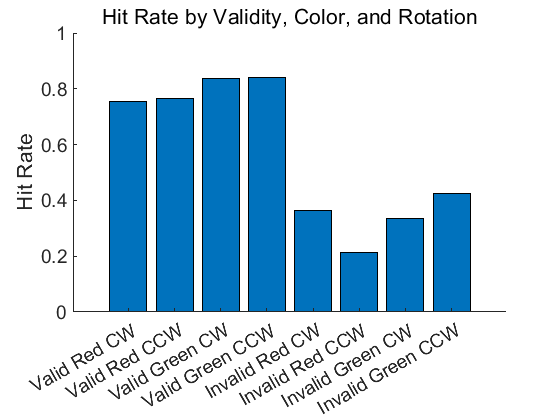

validRedCW              = trialValid & redChanges == 1 & gratingTurn == 1;
validRedCCW             = trialValid & redChanges == 1 & gratingTurn == -1;
validGreenCW            = trialValid & greenChanges == 1 & gratingTurn == 1;
validGreenCCW           = trialValid & greenChanges == 1 & gratingTurn == -1;

correctValidRedCW       = correctValid & redChanges == 1 & gratingTurn == 1;
correctValidRedCCW      = correctValid & redChanges == 1 & gratingTurn == -1;
correctValidGreenCW     = correctValid & greenChanges == 1 & gratingTurn == 1;
correctValidGreenCCW    = correctValid & greenChanges == 1 & gratingTurn == -1;

invalidRedCW            = trialInvalid & redChanges == 1 & gratingTurn == 1;
invalidRedCCW           = trialInvalid & redChanges == 1 & gratingTurn == -1;
invalidGreenCW          = trialInvalid & greenChanges == 1 & gratingTurn == 1;
invalidGreenCCW         = trialInvalid & greenChanges == 1 & gratingTurn == -1;

correctInvalidRedCW     = correctInvalid & redChanges == 1 & gratingTurn == 1;
correctInvalidRedCCW    = correctInvalid & redChanges == 1 & gratingTurn == -1;
correctInvalidGreenCW   = correctInvalid & greenChanges == 1 & gratingTurn == 1;
correctInvalidGreenCCW  = correctInvalid & greenChanges == 1 & gratingTurn == -1;

hitRateValidRedCW       = sum(correctValidRedCW, "all") / sum(validRedCW, "all");
hitRateValidRedCCW      = sum(correctValidRedCCW, "all") / sum(validRedCCW, "all");
hitRateValidGreenCW     = sum(correctValidGreenCW, "all") / sum(validGreenCW, "all");
hitRateValidGreenCCW    = sum(correctValidGreenCCW, "all") / sum(validGreenCCW, "all");

hitRateInvalidRedCW     = sum(correctInvalidRedCW, "all") / sum(invalidRedCW, "all");
hitRateInvalidRedCCW    = sum(correctInvalidRedCCW, "all") / sum(invalidRedCCW, "all");
hitRateInvalidGreenCW   = sum(correctInvalidGreenCW, "all") / sum(invalidGreenCW, "all");
hitRateInvalidGreenCCW  = sum(correctInvalidGreenCCW, "all") / sum(invalidGreenCCW, "all");

figure
bar([hitRateValidRedCW, hitRateValidRedCCW, hitRateValidGreenCW, hitRateValidGreenCCW, ...
    hitRateInvalidRedCW, hitRateInvalidRedCCW, hitRateInvalidGreenCW, hitRateInvalidGreenCCW])
ylim([0 1])
box off

ax = gca;
ax.FontSize = 14; 
title("Hit Rate by Validity, Color, and Rotation", "FontSize", 16, "FontWeight", "normal")
ylabel("Hit Rate", "FontSize", 16)
xticklabels(["Valid Red CW", "Valid Red CCW", "Valid Green CW", "Valid Green CCW", ...
    "Invalid Red CW", "Invalid Red CCW", "Invalid Green CW", "Invalid Green CCW"])
exportgraphics(gcf, "Hit Rate by Validity, Color, and Rotation.png", "Resolution", 300)

### Hit rate by trial type

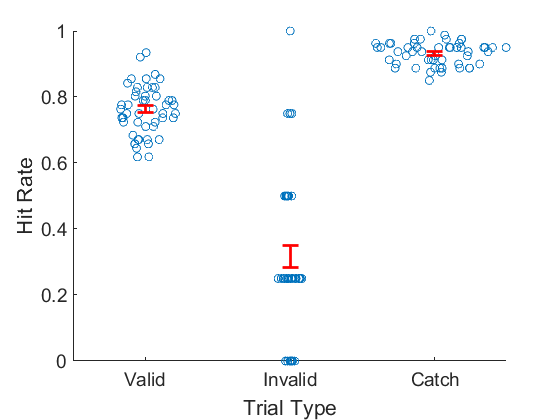

hitRateValid    = sum(correctValid, "all") / sum(trialValid, "all");
hitRateInvalid  = sum(correctInvalid, "all") / sum(trialInvalid, "all");
hitRateCatch    = sum(correctCatch, "all") / sum(trialCatch, "all");

hitRateValidByBlock     = sum(correctValid, 2) ./ sum(trialValid, 2);
hitRateInvalidByBlock   = sum(correctInvalid, 2) ./ sum(trialInvalid, 2);
hitRateCatchByBlock     = sum(correctCatch, 2) ./ sum(trialCatch, 2);

hitRateValid_SEM    = std(hitRateValidByBlock) / sqrt(trialBlocks);
hitRateInvalid_SEM  = std(hitRateInvalidByBlock) / sqrt(trialBlocks);
hitRateCatch_SEM    = std(hitRateCatchByBlock) / sqrt(trialBlocks);

xValSwarm = [ones(trialBlocks, 1); 2 * ones(trialBlocks, 1); 3 * ones(trialBlocks, 1)];

figure
swarm1 = swarmchart(xValSwarm, [hitRateValidByBlock; hitRateInvalidByBlock; hitRateCatchByBlock]);
hold on
eb(1) = errorbar(1, hitRateValid, hitRateValid_SEM, "r", "LineWidth", 2, "CapSize", 12);
eb(2) = errorbar(2, hitRateInvalid, hitRateInvalid_SEM, "r", "LineWidth", 2, "CapSize", 12);
eb(3) = errorbar(3, hitRateCatch, hitRateCatch_SEM, "r", "LineWidth", 2, "CapSize", 12);
hold off

swarm1.XJitterWidth = 1;
ylim([0 1])
xticks([1 2 3])

ax = gca;
ax.FontSize = 14;
xlabel("Trial Type", "FontSize", 16)
ylabel("Hit Rate", "FontSize", 16)
xticklabels(["Valid", "Invalid", "Catch"])
exportgraphics(gcf, "Hit Rate By Trial Type.png", "Resolution", 300)

### Reaction time by trial type

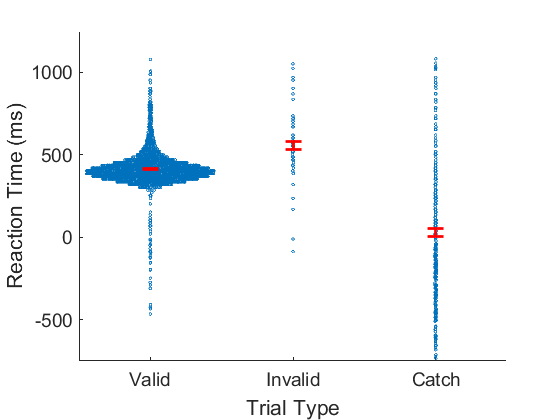

validRT         = trialRT(trialValid & ~isnan(trialRT));
invalidRT       = trialRT(trialInvalid & ~isnan(trialRT));
catchRT         = trialRT(trialCatch & ~isnan(trialRT));

validRT_Mn      = mean(validRT);
invalidRT_Mn    = mean(invalidRT);
catchRT_Mn      = mean(catchRT);

validRT_SEM     = std(validRT) / sqrt(length(validRT));
invalidRT_SEM   = std(invalidRT) / sqrt(length(invalidRT));
catchRT_SEM     = std(catchRT) / sqrt(length(catchRT));

xValues1 = [ones(length(validRT), 1); 2 * ones(length(invalidRT), 1); 3 * ones(length(catchRT), 1)];

figure
swarmchart(xValues1, [validRT; invalidRT; catchRT], 4);
hold on
eb(1) = errorbar(1, validRT_Mn, validRT_SEM, "r", "LineWidth", 2, "CapSize", 12);
eb(2) = errorbar(2, invalidRT_Mn, invalidRT_SEM, "r", "LineWidth", 2, "CapSize", 12);
eb(3) = errorbar(3, catchRT_Mn, catchRT_SEM, "r", "LineWidth", 2, "CapSize", 12);
hold off
xticks([1 2 3])
ylim([-750 1250])

ax = gca;
ax.FontSize = 14;
xlabel("Trial Type", "FontSize", 16)
ylabel("Reaction Time (ms)", "FontSize", 16)
xticklabels(["Valid", "Invalid", "Catch"])
exportgraphics(gcf, "Reaction Time By Trial Type.png", "Resolution", 300)

### Reaction time by trial type 2

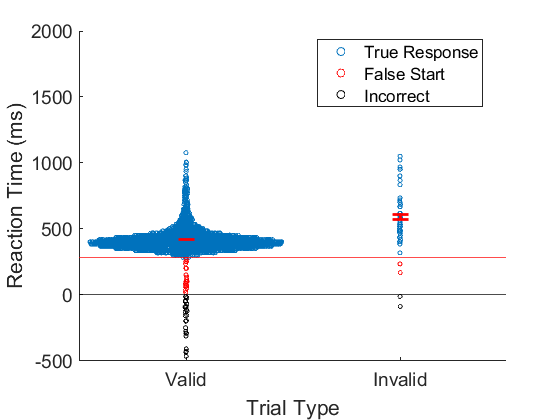

validRTTrue         = validRT(validRT >= 285);
validRTFalse        = validRT(validRT < 285 & validRT > 0);
validRTIncorrect    = validRT(validRT < 0);
invalidRTTrue       = invalidRT(invalidRT >= 285);
invalidRTFalse      = invalidRT(invalidRT < 285 & invalidRT > 0);
invalidRTIncorrect  = invalidRT(invalidRT < 0);

validRTTrue_Mn      = mean(validRTTrue);
invalidTrueRT_Mn    = mean(invalidRTTrue);

validRTTrue_SEM     = std(validRTTrue) / sqrt(length(validRTTrue));
invalidRTTrue_SEM   = std(invalidRTTrue) / sqrt(length(invalidRTTrue));

xValuesTrue = [ones(length(validRTTrue), 1); 2 * ones(length(invalidRTTrue), 1)];
xValuesFalse = [ones(length(validRTFalse), 1); 2 * ones(length(invalidRTFalse), 1)];
xValuesIncorrect = [ones(length(validRTIncorrect), 1); 2 * ones(length(invalidRTIncorrect), 1)];

figure
swarmchart(xValuesTrue, [validRTTrue; invalidRTTrue], 10);
hold on
swarmchart(xValuesFalse, [validRTFalse; invalidRTFalse], 10, "r", "XJitterWidth", 0.01);
swarmchart(xValuesIncorrect, [validRTIncorrect; invalidRTIncorrect], 10, "k", "XJitterWidth", 0.01);
eb(1) = errorbar(1, validRTTrue_Mn, validRTTrue_SEM, "r", "LineWidth", 2, "CapSize", 12);
eb(2) = errorbar(2, invalidTrueRT_Mn, invalidRTTrue_SEM, "r", "LineWidth", 2, "CapSize", 12);
yline(285, "r")
yline(0, "k")
hold off
xticks([1 2 3])
ylim([-500 2000])

ax = gca;
ax.FontSize = 14;
xlabel("Trial Type", "FontSize", 16)
ylabel("Reaction Time (ms)", "FontSize", 16)
xticklabels(["Valid", "Invalid", "Catch"])
legend(["True Response", "False Start", "Incorrect"], "Location", "best")
exportgraphics(gcf, "Reaction Time By Trial Type No Catch.png", "Resolution", 300)

### Round S1 durations to match frame rate and plot histogram on valid trials

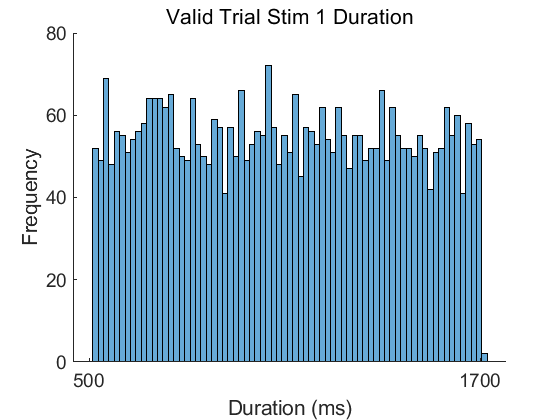

S1Timing = (S1OffTime - S1OnTime) * 1000;       % Convert to msec
validS1 = round(S1Timing(trialValid));

figure
histogram(validS1, 73)
xticks([500 1700])
box off
ax = gca;
ax.FontSize = 14;
title("Valid Trial Stim 1 Duration", "FontSize", 16, "FontWeight", "normal")
xlabel("Duration (ms)")
ylabel("Frequency")
exportgraphics(gcf, "Valid Trial Stim 1 Duration Frequencies.png", "Resolution", 300)

### Collective control plots

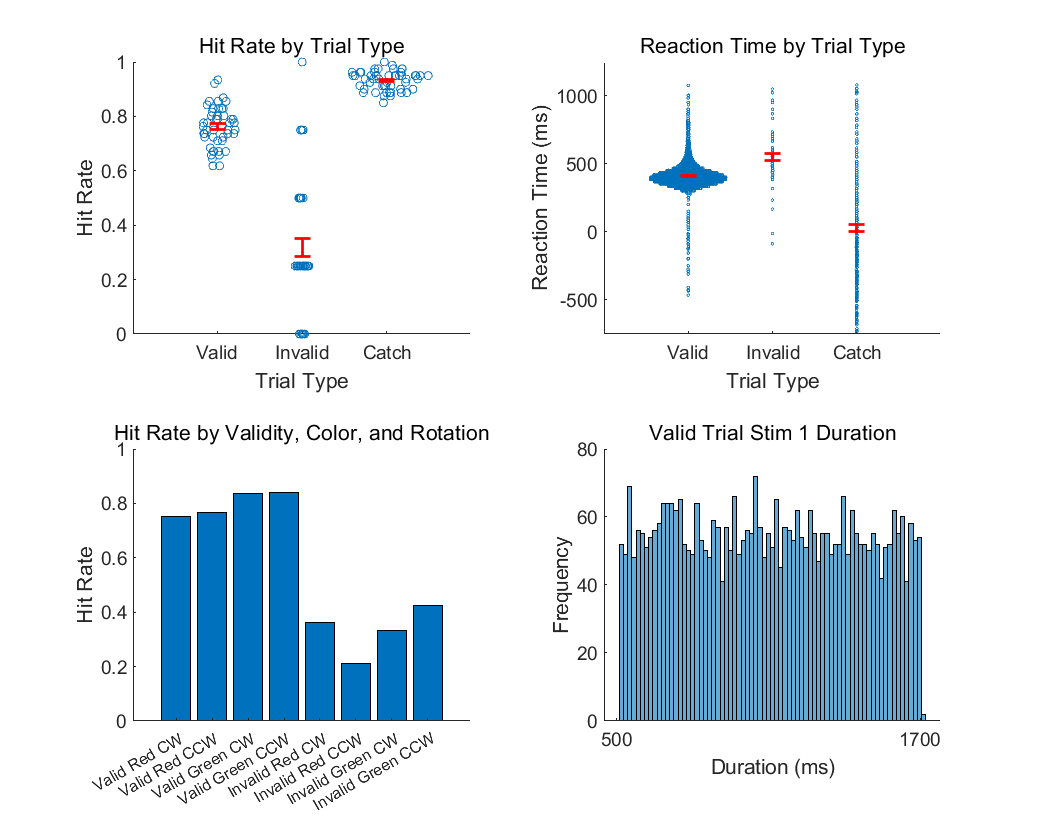

figure('Units', 'inches', 'OuterPosition', [0.5, 0.5, 11, 9])
tiledlayout(2, 2);
nexttile
    swarm1 = swarmchart(xValSwarm, [hitRateValidByBlock; hitRateInvalidByBlock; hitRateCatchByBlock]);
    hold on
    eb(1) = errorbar(1, hitRateValid, hitRateValid_SEM, "r", "LineWidth", 2, "CapSize", 12);
    eb(2) = errorbar(2, hitRateInvalid, hitRateInvalid_SEM, "r", "LineWidth", 2, "CapSize", 12);
    eb(3) = errorbar(3, hitRateCatch, hitRateCatch_SEM, "r", "LineWidth", 2, "CapSize", 12);
    hold off
    swarm1.XJitterWidth = 1;
    ylim([0 1])
    xticks([1 2 3])
    ax = gca;
    ax.FontSize = 14;
    title("Hit Rate by Trial Type", "FontSize", 16, "FontWeight", "normal")
    xlabel("Trial Type", "FontSize", 16)
    ylabel("Hit Rate", "FontSize", 16)
    xticklabels(["Valid", "Invalid", "Catch"])
    exportgraphics(gcf, "Hit Rate By Trial Type.png", "Resolution", 300)
nexttile
    swarmchart(xValues1, [validRT; invalidRT; catchRT], 4);
    hold on
    eb(1) = errorbar(1, validRT_Mn, validRT_SEM, "r", "LineWidth", 2, "CapSize", 12);
    eb(2) = errorbar(2, invalidRT_Mn, invalidRT_SEM, "r", "LineWidth", 2, "CapSize", 12);
    eb(3) = errorbar(3, catchRT_Mn, catchRT_SEM, "r", "LineWidth", 2, "CapSize", 12);
    hold off
    xticks([1 2 3])
    ylim([-750 1250])
    ax = gca;
    ax.FontSize = 14;
    title("Reaction Time by Trial Type", "FontSize", 16, "FontWeight", "normal")
    xlabel("Trial Type", "FontSize", 16)
    ylabel("Reaction Time (ms)", "FontSize", 16)
    xticklabels(["Valid", "Invalid", "Catch"])
nexttile
   bar([hitRateValidRedCW, hitRateValidRedCCW, hitRateValidGreenCW, hitRateValidGreenCCW, ...
        hitRateInvalidRedCW, hitRateInvalidRedCCW, hitRateInvalidGreenCW, hitRateInvalidGreenCCW])
    ylim([0 1])
    box off
    ax = gca;
    ax.XAxis.FontSize = 12;
    ax.YAxis.FontSize = 14; 
    title("Hit Rate by Validity, Color, and Rotation", "FontSize", 16, "FontWeight", "normal")
    ylabel("Hit Rate", "FontSize", 16)
    xticklabels(["Valid Red CW", "Valid Red CCW", "Valid Green CW", "Valid Green CCW", ...
        "Invalid Red CW", "Invalid Red CCW", "Invalid Green CW", "Invalid Green CCW"])
nexttile
    histogram(validS1, 73)
    xticks([500 1700])
    box off
    ax = gca;
    ax.FontSize = 14;
    title("Valid Trial Stim 1 Duration", "FontSize", 16, "FontWeight", "normal")
    xlabel("Duration (ms)")
    ylabel("Frequency")
exportgraphics(gcf, "Kastner Control.png", 'Resolution', 300)

### Plot valid trial hit rate vs S1 duration 83 msec (5 frame) moving mean with individual points

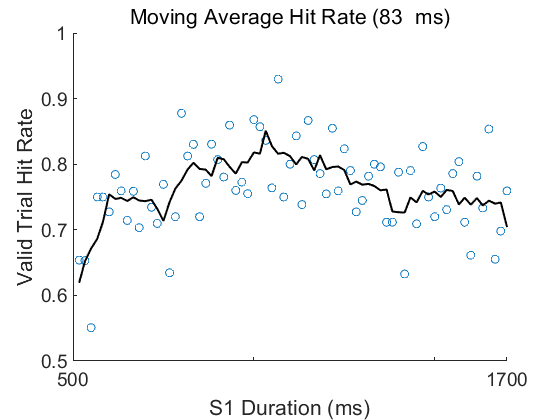

correctValidS1 = round(S1Timing(correctValid));
uniqueS1 = unique(validS1);
uniqueS1 = uniqueS1(1:72);      % Importantly removes two trials in which the S1 duration was one frame longer than max (1717 msec)

validS1HitRate = nan(length(uniqueS1), 1);
for n = 1:length(uniqueS1)
    loopValid = sum(ismember(validS1, uniqueS1(n)));
    loopValidCorrect = sum(ismember(correctValidS1, uniqueS1(n)));
    validS1HitRate(n) = loopValidCorrect / loopValid;
end

hitRateMoveMean83 = movmean(validS1HitRate, 5);

figure
scatter(uniqueS1, validS1HitRate, "MarkerEdgeColor", "#0072BD")
hold on
plot(uniqueS1, hitRateMoveMean83, "k", "LineWidth", 1.5)
hold off

xticks([500 1000 1500 1700])
xticklabels([500, "", "", 1700])
xlim([500 1700])

ax = gca;
ax.FontSize = 14;
title("Moving Average Hit Rate (83  ms)", "FontSize", 16, "FontWeight", "normal")
xlabel("S1 Duration (ms)", "FontSize", 16)
ylabel("Valid Trial Hit Rate", "FontSize", 16)
exportgraphics(gcf, "Hit Rate vs S1 Movmean with Points.png", "Resolution", 300)

### Plot valid trial hit rate vs S1 duration 83 msec (5 frame) moving mean

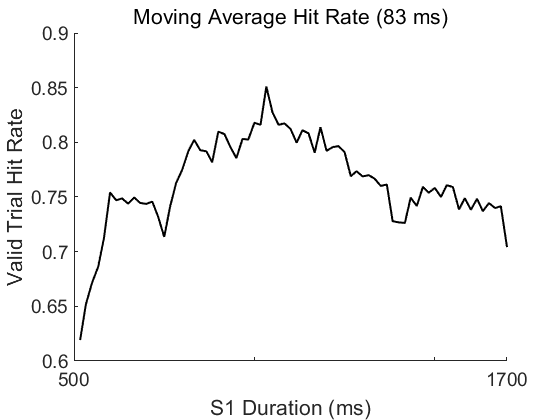

figure
plot(uniqueS1, hitRateMoveMean83, "k", "LineWidth", 1.5)
box off
xticks([500 1000 1500 1700])
xticklabels([500, "", "", 1700])
xlim([500 1700])

ax = gca;
ax.FontSize = 14;
title("Moving Average Hit Rate (83 ms)", "FontSize", 16, "FontWeight", "normal")
xlabel("S1 Duration (ms)", "FontSize", 16)
ylabel("Valid Trial Hit Rate", "FontSize", 16)
exportgraphics(gcf, "Hit Rate vs S1 Movmean.png", "Resolution", 300)

### Plot valid trial hit rate vs S1 duration Kastner-style line with individual points

"We shifted a 100 ms window in steps of 1 ms from 500 – 1700 ms and recalculated the hit rate

across all validly cued trials in the respective time window."

startWindow = 500;
endWindow = 600;
loopValue = 1;
hitRateWindow = nan(1100, 1);

while endWindow < 1700
    windowS1 = S1Timing >= startWindow & S1Timing <= endWindow;
    hitRateWindow(loopValue) = sum(correctValid(windowS1), "all") / sum(trialValid(windowS1), "all");
    startWindow = startWindow + 1;
    endWindow = endWindow + 1;
    loopValue = loopValue + 1;
end

"The traces were smoothed and missing data points interpolated using a 25-point boxcar moving average."

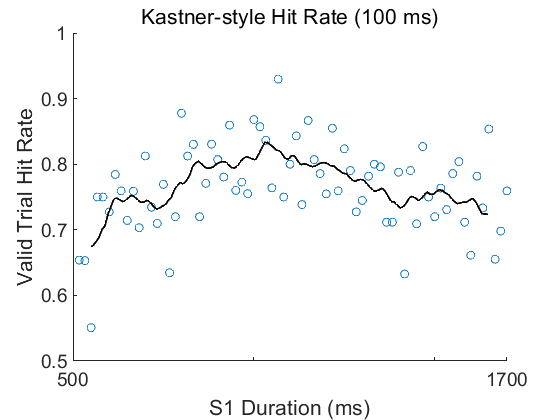

hitRateKastner100 = movmean(hitRateWindow, 25);
xValKastner100 = 551:1650;

figure
scatter(uniqueS1, validS1HitRate, "MarkerEdgeColor", "#0072BD")
hold on
plot(xValKastner100, hitRateKastner100, "k", "LineWidth", 1.5)
hold off

xticks([500 1000 1500 1700])
xticklabels([500, "", "", 1700])
xlim([500 1700])

ax = gca;
ax.FontSize = 14;
title("Kastner-style Hit Rate (100 ms)", "FontSize", 16, "FontWeight", "normal")
xlabel("S1 Duration (ms)", "FontSize", 16)
ylabel("Valid Trial Hit Rate", "FontSize", 16)
legend("off")
exportgraphics(gcf, "Hit Rate vs S1 Kastner with Points.png", "Resolution", 300)

### Plot valid trial hit rate vs S1 duration Kastner-style line

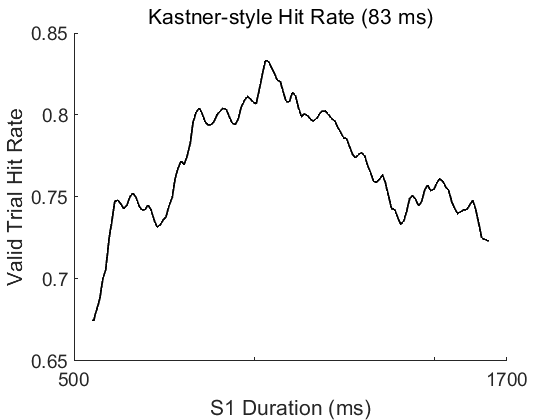

figure
plot(xValKastner100, hitRateKastner100, "k", "LineWidth", 1.5)
box off
xticks([500 1000 1500 1700])
xticklabels([500, "", "", 1700])
xlim([500 1700])

ax = gca;
ax.FontSize = 14;
title("Kastner-style Hit Rate (83 ms)", "FontSize", 16, "FontWeight", "normal")
xlabel("S1 Duration (ms)", "FontSize", 16)
ylabel("Valid Trial Hit Rate", "FontSize", 16)
legend("off")
exportgraphics(gcf, "Hit Rate vs S1 Kastner.png", "Resolution", 300)

### Plot valid trial reaction time vs S1 duration 83 msec moving mean with SEM and individual points

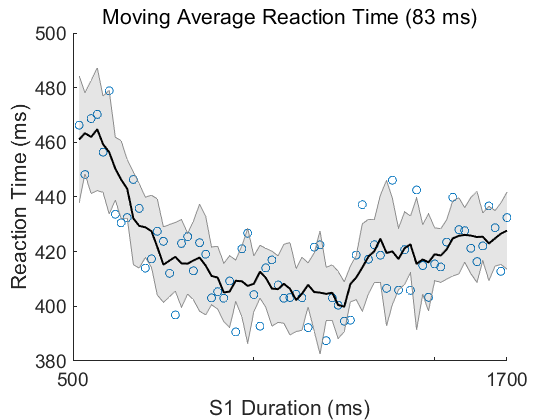

validS1RT       = nan(length(uniqueS1), 1);
validS1RT_SEM   = nan(length(uniqueS1), 1);
correctValidRT  = trialRT(correctValid);

for n = 1:length(uniqueS1)
    loopValid = ismember(correctValidS1, uniqueS1(n));
    validS1RT(n) = mean(correctValidRT(loopValid));
    validS1RT_SEM(n) = std(correctValidRT(loopValid)) / sqrt(length(correctValidRT(loopValid)));
end

RTMoveMean83 = movmean(validS1RT, 6);

figure
scatter(uniqueS1, validS1RT, "MarkerEdgeColor", "#0072BD")
hold on
plot(uniqueS1, RTMoveMean83, "k", "LineWidth", 1.5)
shadedErrorBar(uniqueS1, RTMoveMean83, validS1RT_SEM, "patchSaturation", 0.1)
hold off

xticks([500 1000 1500 1700])
xticklabels([500, "", "", 1700])
xlim([500 1700])

ax = gca;
ax.FontSize = 14;
title("Moving Average Reaction Time (83 ms)", "FontSize", 16, "FontWeight", "normal")
xlabel("S1 Duration (ms)", "FontSize", 16)
ylabel("Reaction Time (ms)", "FontSize", 16)
exportgraphics(gcf, "Reaction Time vs S1 Movmean with Points.png", "Resolution", 300)

### Plot valid trial reaction time vs S1 duration 83 msec moving mean

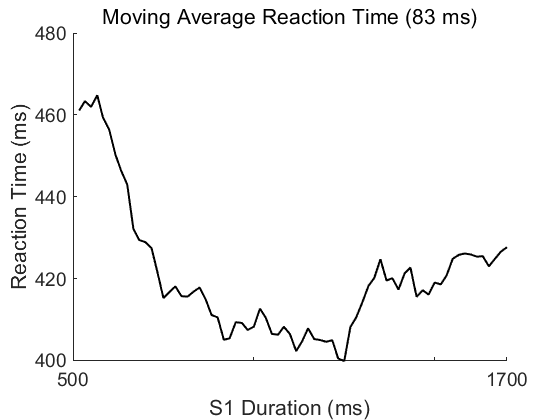

figure
plot(uniqueS1, RTMoveMean83, "k", "LineWidth", 1.5)
box off

xticks([500 1000 1500 1700])
xticklabels([500, "", "", 1700])
xlim([500 1700])

ax = gca;
ax.FontSize = 14;
title("Moving Average Reaction Time (83 ms)", "FontSize", 16, "FontWeight", "normal")
xlabel("S1 Duration (ms)", "FontSize", 16)
ylabel("Reaction Time (ms)", "FontSize", 16)
exportgraphics(gcf, "Reaction Time vs S1 Movmean.png", "Resolution", 300)

### Plot valid trial reaction time vs S1 duration Kastner-style line with individual points

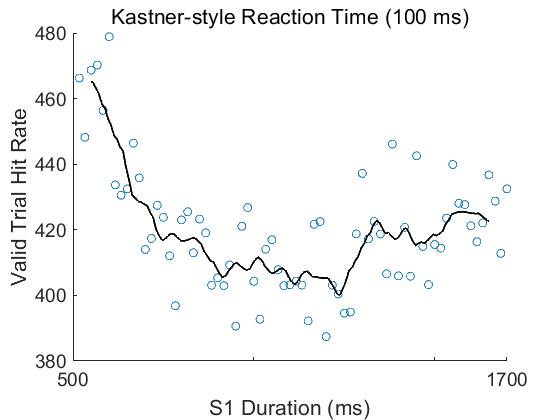

startWindow = 500;
endWindow = 600;
loopValue = 1;
RTWindow = nan(1100, 1);

while endWindow < 1700
    windowS1 = S1Timing >= startWindow & S1Timing <= endWindow;
    RTWindow(loopValue) = mean(trialRT(windowS1 & correctValid));
    startWindow = startWindow + 1;
    endWindow = endWindow + 1;
    loopValue = loopValue + 1;
end

RTKastner100 = movmean(RTWindow, 25);
xValKastner100 = 551:1650;

figure
scatter(uniqueS1, validS1RT, "MarkerEdgeColor", "#0072BD")
hold on
plot(xValKastner100, RTKastner100, "k", "LineWidth", 1.5)
hold off

xticks([500 1000 1500 1700])
xticklabels([500, "", "", 1700])
xlim([500 1700])

ax = gca;
ax.FontSize = 14;
title("Kastner-style Reaction Time (100 ms)", "FontSize", 16, "FontWeight", "normal")
xlabel("S1 Duration (ms)", "FontSize", 16)
ylabel("Valid Trial Hit Rate", "FontSize", 16)
legend("off")
exportgraphics(gcf, "Reaction Time vs S1 Kastner with Points.png", "Resolution", 300)

### Plot valid trial reaction time vs S1 duration Kastner-style line

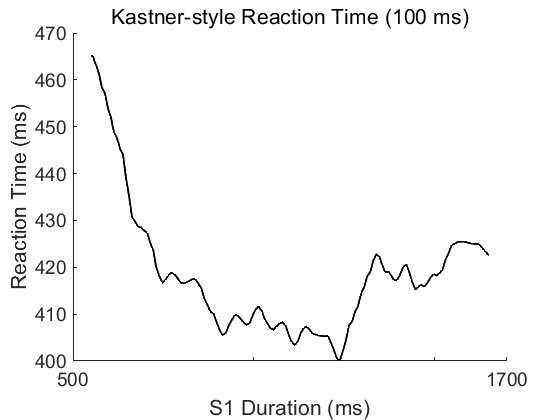

figure
plot(xValKastner100, RTKastner100, "k", "LineWidth", 1.5)
box off

xticks([500 1000 1500 1700])
xticklabels([500, "", "", 1700])
xlim([500 1700])

ax = gca;
ax.FontSize = 14;
title("Kastner-style Reaction Time (100 ms)", "FontSize", 16, "FontWeight", "normal")
xlabel("S1 Duration (ms)", "FontSize", 16)
ylabel("Reaction Time (ms)", "FontSize", 16)
exportgraphics(gcf, "Reaction Time vs S1 Movmean.png", "Resolution", 300)

### Redo moving average and kastner-style lines with a 50 ms window

hitRateMoveMean50 = movmean(validS1HitRate, 3);
RTMoveMean50 = movmean(validS1RT, 3);

startWindow = 500;
endWindow = 550;
loopValue = 1;
hitRateWindow50 = nan(1150, 1);
RTWindow50 = nan(1150, 1);

while endWindow < 1700
    windowS1 = S1Timing >= startWindow & S1Timing <= endWindow;
    hitRateWindow50(loopValue) = sum(correctValid(windowS1), "all") / sum(trialValid(windowS1), "all");
    RTWindow50(loopValue) = mean(trialRT(windowS1 & correctValid));
    startWindow = startWindow + 1;
    endWindow = endWindow + 1;
    loopValue = loopValue + 1;
end

hitRateKastner50 = movmean(hitRateWindow50, 25);
RTKastner50 = movmean(RTWindow50, 25);

xValKastner50 = 526:1675;

### Behavioral time course plots for hit rate

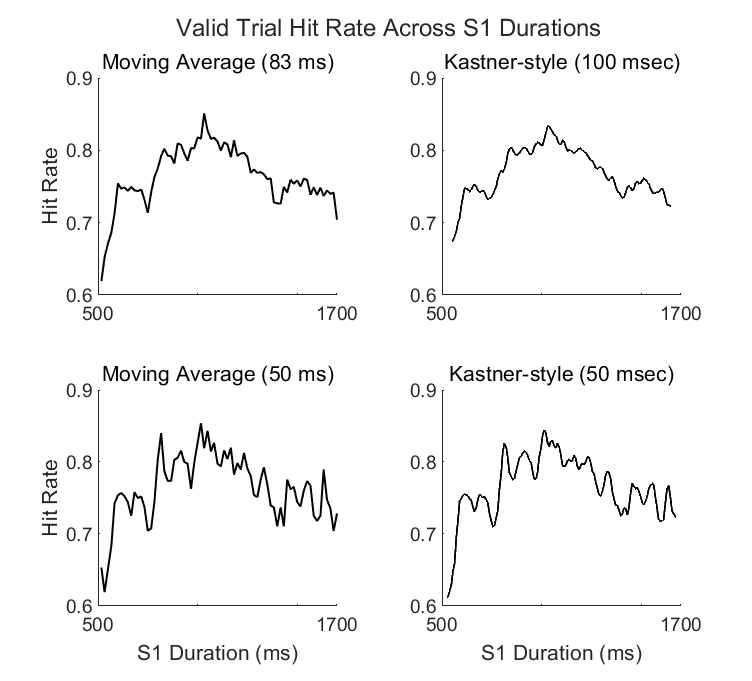

figure  ('Units', 'inches', 'OuterPosition', [0.5, 0.5, 8, 7.5])
t = tiledlayout(2, 2);
title(t, "Valid Trial Hit Rate Across S1 Durations", "FontSize", 18)
nexttile
    plot(uniqueS1, hitRateMoveMean83, "k", "LineWidth", 1.5)
    box off
    xticks([500 1000 1500 1700])
    xticklabels([500, "", "", 1700])
    xlim([500 1700])
    ylim([0.6 0.9])
    ax = gca;
    ax.FontSize = 14;
    title("Moving Average (83 ms)", "FontSize", 16, "FontWeight", "normal")
    ylabel("Hit Rate", "FontSize", 16)
nexttile
    plot(xValKastner100, hitRateKastner100, "k", "LineWidth", 1.5)
    box off
    xticks([500 1000 1500 1700])
    xticklabels([500, "", "", 1700])
    xlim([500 1700])
    ylim([0.6 0.9])
    ax = gca;
    ax.FontSize = 14;
    title("Kastner-style (100 msec)", "FontSize", 16, "FontWeight", "normal")
nexttile
    plot(uniqueS1, hitRateMoveMean50, "k", "LineWidth", 1.5)
    box off
    xticks([500 1000 1500 1700])
    xticklabels([500, "", "", 1700])
    xlim([500 1700])
    ylim([0.6 0.9])
    ax = gca;
    ax.FontSize = 14;
    title("Moving Average (50 ms)", "FontSize", 16, "FontWeight", "normal")
    xlabel("S1 Duration (ms)", "FontSize", 16)
    ylabel("Hit Rate", "FontSize", 16)
nexttile
    plot(xValKastner50, hitRateKastner50, "k", "LineWidth", 1.5)
    box off
    xticks([500 1000 1500 1700])
    xticklabels([500, "", "", 1700])
    xlim([500 1700])
    ylim([0.6 0.9])
    ax = gca;
    ax.FontSize = 14;
    title("Kastner-style (50 msec)", "FontSize", 16, "FontWeight", "normal")
    xlabel("S1 Duration (ms)", "FontSize", 16)
exportgraphics(gcf, "Hit Rate Time Courses.png", 'Resolution', 300)

### Behavioral time course plots for reaction time

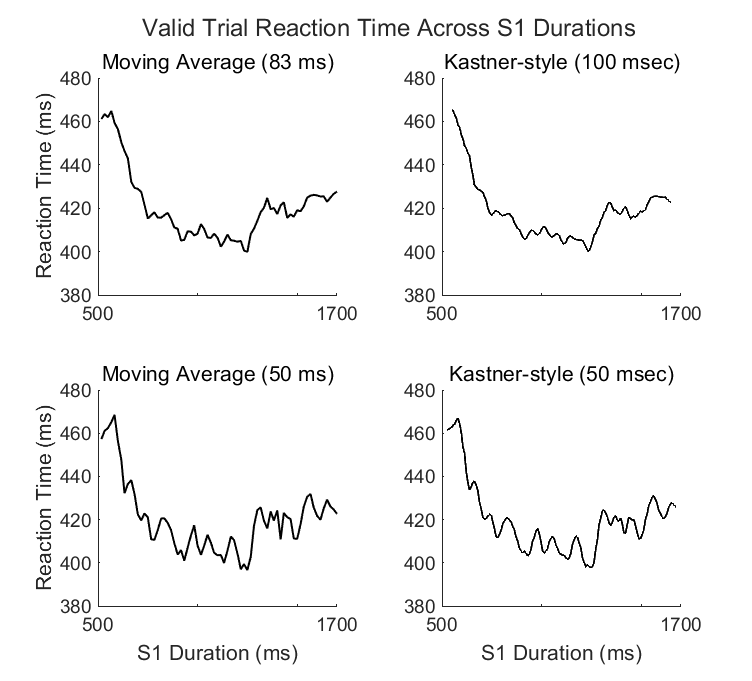

figure('Units', 'inches', 'OuterPosition', [0.5, 0.5, 8, 7.5])
t = tiledlayout(2, 2);
title(t, "Valid Trial Reaction Time Across S1 Durations", "FontSize", 18)
nexttile
    plot(uniqueS1, RTMoveMean83, "k", "LineWidth", 1.5)
    box off
    xticks([500 1000 1500 1700])
    xticklabels([500, "", "", 1700])
    xlim([500 1700])
    ylim([380 480])
    ax = gca;
    ax.FontSize = 14;
    title("Moving Average (83 ms)", "FontSize", 16, "FontWeight", "normal")
    ylabel("Reaction Time (ms)", "FontSize", 16)
nexttile
    plot(xValKastner100, RTKastner100, "k", "LineWidth", 1.5)
    box off
    xticks([500 1000 1500 1700])
    xticklabels([500, "", "", 1700])
    xlim([500 1700])
    ylim([380 480])
    ax = gca;
    ax.FontSize = 14;
    title("Kastner-style (100 msec)", "FontSize", 16, "FontWeight", "normal")
nexttile
    plot(uniqueS1, RTMoveMean50, "k", "LineWidth", 1.5)
    box off
    xticks([500 1000 1500 1700])
    xticklabels([500, "", "", 1700])
    xlim([500 1700])
    ylim([380 480])
    ax = gca;
    ax.FontSize = 14;
    title("Moving Average (50 ms)", "FontSize", 16, "FontWeight", "normal")
    xlabel("S1 Duration (ms)", "FontSize", 16)
    ylabel("Reaction Time (ms)", "FontSize", 16)
nexttile
    plot(xValKastner50, RTKastner50, "k", "LineWidth", 1.5)
    box off
    xticks([500 1000 1500 1700])
    xticklabels([500, "", "", 1700])
    xlim([500 1700])
    ylim([380 480])
    ax = gca;
    ax.FontSize = 14;
    title("Kastner-style (50 msec)", "FontSize", 16, "FontWeight", "normal")
    xlabel("S1 Duration (ms)", "FontSize", 16)
exportgraphics(gcf, "Reaction Time Across S1 Durations.png", 'Resolution', 300)

### Advanced plots

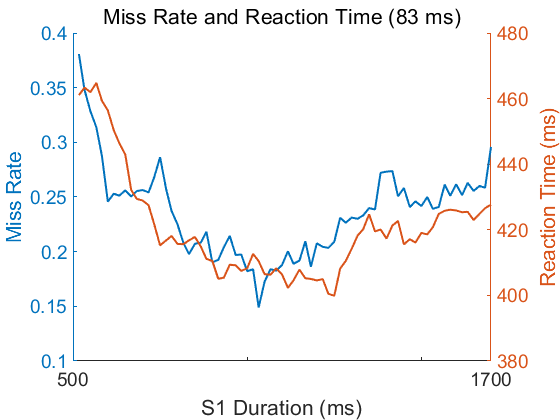

figure
    yyaxis left
        plot(uniqueS1, 1 - hitRateMoveMean83, "k", "LineWidth", 1.5, "Color", "#0072BD")
        ylabel("Miss Rate")
    yyaxis right
        plot(uniqueS1, RTMoveMean83, "k", "LineWidth", 1.5, "Color", "#D95319")
        ylabel("Reaction Time (ms)", "FontSize",  16)
    box off
    ax = gca;
    ax.FontSize = 14;
    xticks([500 1000 1500 1700])
    xticklabels([500, "", "", 1700])
    xlim([500 1700])
    title("Miss Rate and Reaction Time (83 ms)", "FontSize", 16, "FontWeight", "normal")
    xlabel("S1 Duration (ms)", "FontSize",  16)
exportgraphics(gcf, "Miss Rate vs Reaction Time.png", 'Resolution', 300)

### Fourier Analysis

FFT_HitRateMoveMean83 = fft(hitRateMoveMean83);
FFT_HitRateMoveMean50 = fft(hitRateMoveMean50);

FFT_HitRateKastner100 = fft(hitRateKastner100);
FFT_HitRateKastner50 = fft(hitRateKastner50);

FFT_RTMoveMean83 = fft(RTMoveMean83);
FFT_RTMoveMean50 = fft(RTMoveMean50);

FFT_RTKastner100 = fft(RTKastner100);
FFT_RTKastner50 = fft(RTKastner50);

xValsMoveMeanFourier = (0:(72 - 1)) * 60/72;            % (0:(signalLength - 1)) * (samplingFreq/signalLength)
xValsKastner100Fourier = (0:(1100 - 1)) * 1000/1100;     % (0:(signalLength - 1)) * (samplingFreq/signalLength)
xValsKastner50Fourier = (0:(1150 - 1)) * 1000/1150;     % (0:(signalLength - 1)) * (samplingFreq/signalLength)

### Fourier analysis plots for hit rate

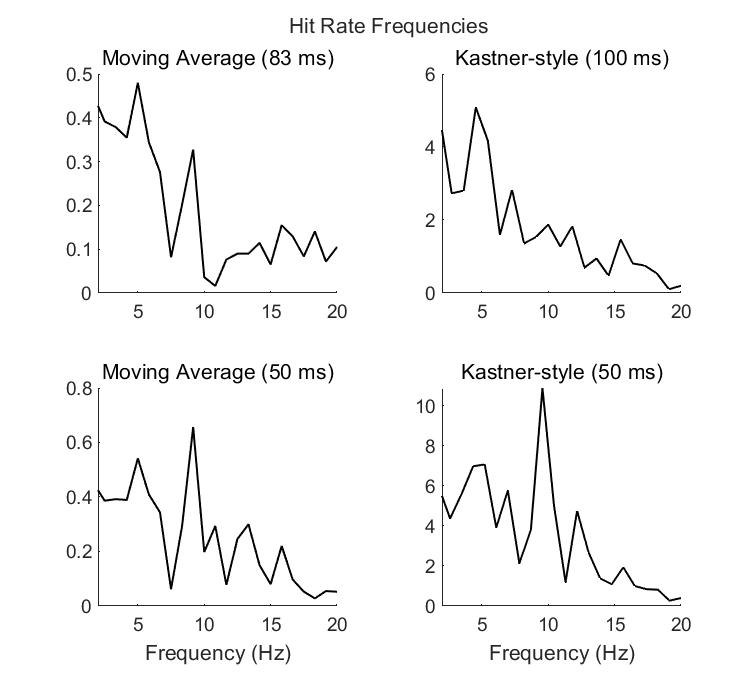

figure('Units', 'inches', 'OuterPosition', [0.5, 0.5, 8, 7.5])
t = tiledlayout(2, 2);
title(t, "Hit Rate Frequencies", "FontSize", 16)
nexttile
    plot(xValsMoveMeanFourier(2:end), abs(FFT_HitRateMoveMean83(2:end)), "k", "LineWidth", 1.5)
    box off
    xlim([2 20])
    ax = gca;
    ax.FontSize = 14;
    title("Moving Average (83 ms)", "FontSize", 16, "FontWeight", "normal")
nexttile
    plot(xValsKastner100Fourier(2:end), abs(FFT_HitRateKastner100(2:end)), "k", "LineWidth", 1.5)
    box off
    xlim([2 20])
    ax = gca;
    ax.FontSize = 14;
    title("Kastner-style (100 ms)", "FontSize", 16, "FontWeight", "normal")
nexttile
    plot(xValsMoveMeanFourier(2:end), abs(FFT_HitRateMoveMean50(2:end)), "k", "LineWidth", 1.5)
    box off
    xlim([2 20])
    ax = gca;
    ax.FontSize = 14;
    title("Moving Average (50 ms)", "FontSize", 16, "FontWeight", "normal")
    xlabel("Frequency (Hz)", "FontSize", 16)
nexttile
    plot(xValsKastner50Fourier(2:end), abs(FFT_HitRateKastner50(2:end)), "k", "LineWidth", 1.5)
    box off
    xlim([2 20])
    ax = gca;
    ax.FontSize = 14;
    title("Kastner-style (50 ms)", "FontSize", 16, "FontWeight", "normal")
    xlabel("Frequency (Hz)", "FontSize", 16)
exportgraphics(gcf, "Hit Rate Fourier.png", 'Resolution', 300)

### Fourier analysis plots for reaction time

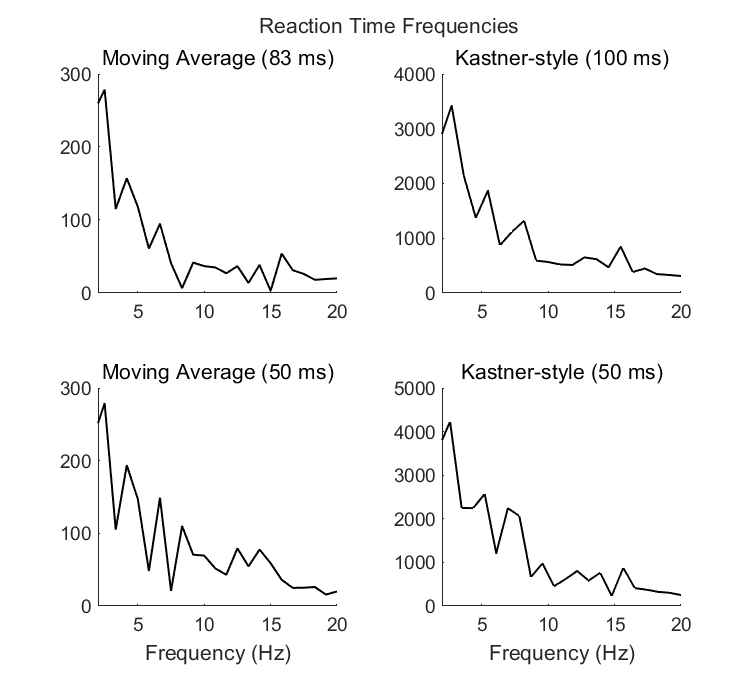

figure('Units', 'inches', 'OuterPosition', [0.5, 0.5, 8, 7.5])
t = tiledlayout(2, 2);
title(t, "Reaction Time Frequencies", "FontSize", 16)
nexttile
    plot(xValsMoveMeanFourier(2:end), abs(FFT_RTMoveMean83(2:end)), "k", "LineWidth", 1.5)
    box off
    xlim([2 20])
    ax = gca;
    ax.FontSize = 14;
    title("Moving Average (83 ms)", "FontSize", 16, "FontWeight", "normal")
nexttile
    plot(xValsKastner100Fourier(2:end), abs(FFT_RTKastner100(2:end)), "k", "LineWidth", 1.5)
    box off
    xlim([2 20])
    ax = gca;
    ax.FontSize = 14;
    title("Kastner-style (100 ms)", "FontSize", 16, "FontWeight", "normal")
nexttile
    plot(xValsMoveMeanFourier(2:end), abs(FFT_RTMoveMean50(2:end)), "k", "LineWidth", 1.5)
    box off
    xlim([2 20])
    ax = gca;
    ax.FontSize = 14;
    title("Moving Average (50 ms)", "FontSize", 16, "FontWeight", "normal")
    xlabel("Frequency (Hz)", "FontSize", 16)
nexttile
    plot(xValsKastner50Fourier(2:end), abs(FFT_RTKastner50(2:end)), "k", "LineWidth", 1.5)
    box off
    xlim([2 20])
    ax = gca;
    ax.FontSize = 14;
    title("Kastner-style (50 ms)", "FontSize", 16, "FontWeight", "normal")
    xlabel("Frequency (Hz)", "FontSize", 16)
exportgraphics(gcf, "Reaction Time Fourier.png", 'Resolution', 300)

### Apply Hanning window and zero pad to increase the frequency resolution

"We obtained spectral estimates from a Fast Fourier Transform (FFT) after applying a Hanning window and zero padding the data to 10 s to increase the frequency resolution to 0.1 Hz."

hitRateMoveMean83H  = hitRateMoveMean83 .* hann(length(hitRateMoveMean83));
hitRateKastner100H  = hitRateKastner100 .* hann(length(hitRateKastner100));
hitRateMoveMean50H  = hitRateMoveMean50 .* hann(length(hitRateMoveMean50));
hitRateKastner50H   = hitRateKastner50 .* hann(length(hitRateKastner50));

RTMoveMean83H   = RTMoveMean83 .* hann(length(RTMoveMean83));
RTKastner100H   = RTKastner100 .* hann(length(RTKastner100));
RTMoveMean50H   = RTMoveMean50 .* hann(length(RTMoveMean50));
RTKastner50H    = RTKastner50 .* hann(length(RTKastner50));

hitRateMoveMean83HP = [hitRateMoveMean83H; zeros(528, 1)];
hitRateKastner100HP = [hitRateKastner100H; zeros(8900, 1)];
hitRateMoveMean50HP = [hitRateMoveMean50H; zeros(528, 1)];
hitRateKastner50HP  = [hitRateKastner50H; zeros(8850, 1)];

RTMoveMean83HP  = [RTMoveMean83H; zeros(528, 1)];
RTKastner100HP  = [RTKastner100H; zeros(8900, 1)];
RTMoveMean50HP  = [RTMoveMean50H; zeros(528, 1)];
RTKastner50HP   = [RTKastner50H; zeros(8850, 1)];

xValsMoveMeanHP = (0:(600 - 1)) * 60/600;       % Freq resolution = 0.1; (0:(signalLength - 1)) * (samplingFreq/signalLength)
xValsKastnerHP = (0:(10000 - 1)) * 1000/10000;  % Freq resolution = 0.1; (0:(signalLength - 1)) * (samplingFreq/signalLength)

FFT_hitRateMoveMean83HP = fft(hitRateMoveMean83HP);
FFT_hitRateKastner100HP = fft(hitRateKastner100HP);
FFT_hitRateMoveMean50HP = fft(hitRateMoveMean50HP);
FFT_hitRateKastner50HP  = fft(hitRateKastner50HP);

FFT_RTMoveMean83HP  = fft(RTMoveMean83HP);
FFT_RTKastner100HP  = fft(RTKastner100HP);
FFT_RTMoveMean50HP  = fft(RTMoveMean50HP);
FFT_RTKastner50HP   = fft(RTKastner50HP);

### Fourier analysis plots with Hanning and zero padding for hit rate

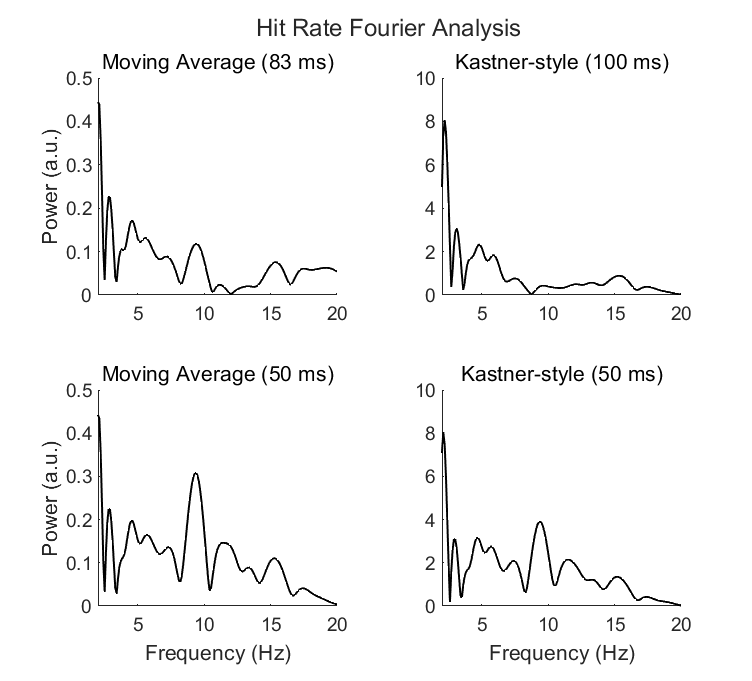

figure('Units', 'inches', 'OuterPosition', [0.5, 0.5, 8, 7.5])
t = tiledlayout(2, 2);
title(t, "Hit Rate Fourier Analysis", "FontSize", 18)
nexttile
    plot(xValsMoveMeanHP(2:end), abs(FFT_hitRateMoveMean83HP(2:end)), "k", "LineWidth", 1.5)
    box off
    xlim([2 20])
    ax = gca;
    ax.FontSize = 14;
    ylabel("Power (a.u.)", "FontSize", 16)
    title("Moving Average (83 ms)", "FontSize", 16, "FontWeight", "normal")
nexttile
    plot(xValsKastnerHP(2:end), abs(FFT_hitRateKastner100HP(2:end)), "k", "LineWidth", 1.5)
    box off
    xlim([2 20])
    ax = gca;
    ax.FontSize = 14;
    title("Kastner-style (100 ms)", "FontSize", 16, "FontWeight", "normal")
nexttile
    plot(xValsMoveMeanHP(2:end), abs(FFT_hitRateMoveMean50HP(2:end)), "k", "LineWidth", 1.5)
    box off
    xlim([2 20])
    ax = gca;
    ax.FontSize = 14;
    title("Moving Average (50 ms)", "FontSize", 16, "FontWeight", "normal")
    xlabel("Frequency (Hz)", "FontSize", 16)
    ylabel("Power (a.u.)", "FontSize", 16)
nexttile
    plot(xValsKastnerHP(2:end), abs(FFT_hitRateKastner50HP(2:end)), "k", "LineWidth", 1.5)
    box off
    xlim([2 20])
    ax = gca;
    ax.FontSize = 14;
    title("Kastner-style (50 ms)", "FontSize", 16, "FontWeight", "normal")
    xlabel("Frequency (Hz)", "FontSize", 16)
exportgraphics(gcf, "Hann and Zero Hit Rates.png", 'Resolution', 300)

### Fourier analysis plots with Hanning and zero padding for hit rate

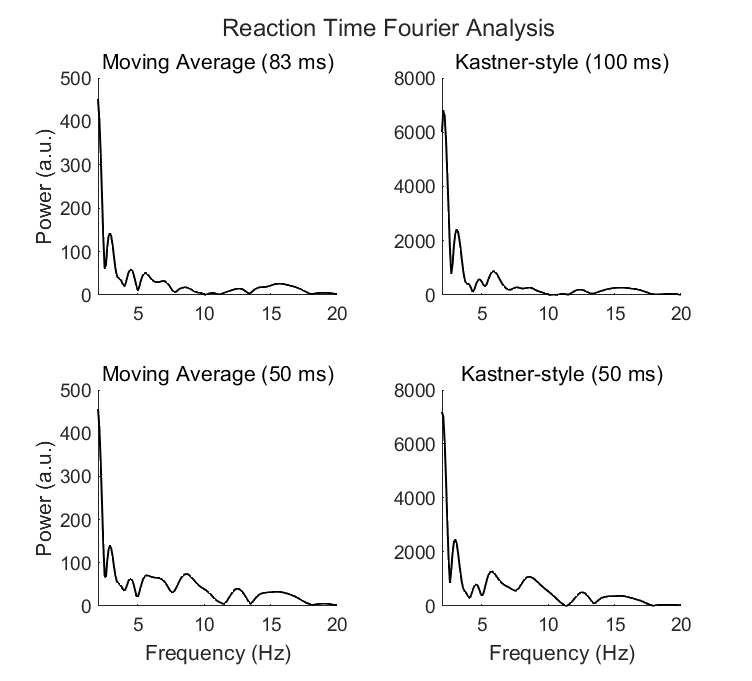

figure('Units', 'inches', 'OuterPosition', [0.5, 0.5, 8, 7.5])
t = tiledlayout(2, 2);
title(t, "Reaction Time Fourier Analysis", "FontSize", 18)
nexttile
    plot(xValsMoveMeanHP(2:end), abs(FFT_RTMoveMean83HP(2:end)), "k", "LineWidth", 1.5)
    box off
    xlim([2 20])
    ax = gca;
    ax.FontSize = 14;
    title("Moving Average (83 ms)", "FontSize", 16, "FontWeight", "normal")
    ylabel("Power (a.u.)", "FontSize", 16)
nexttile
    plot(xValsKastnerHP(2:end), abs(FFT_RTKastner100HP(2:end)), "k", "LineWidth", 1.5)
    box off
    xlim([2 20])
    ax = gca;
    ax.FontSize = 14;
    title("Kastner-style (100 ms)", "FontSize", 16, "FontWeight", "normal")
nexttile
    plot(xValsMoveMeanHP(2:end), abs(FFT_RTMoveMean50HP(2:end)), "k", "LineWidth", 1.5)
    box off
    xlim([2 20])
    ax = gca;
    ax.FontSize = 14;
    title("Moving Average (50 ms)", "FontSize", 16, "FontWeight", "normal")
    xlabel("Frequency (Hz)", "FontSize", 16)
    ylabel("Power (a.u.)", "FontSize", 16)
nexttile
    plot(xValsKastnerHP(2:end), abs(FFT_RTKastner50HP(2:end)), "k", "LineWidth", 1.5)
    box off
    xlim([2 20])
    ax = gca;
    ax.FontSize = 14;
    title("Kastner-style (50 ms)", "FontSize", 16, "FontWeight", "normal")
    xlabel("Frequency (Hz)", "FontSize", 16)
exportgraphics(gcf, "Hann and Zero Reaction Times.png", 'Resolution', 300)

### Hit rate random order analysis with individual lines

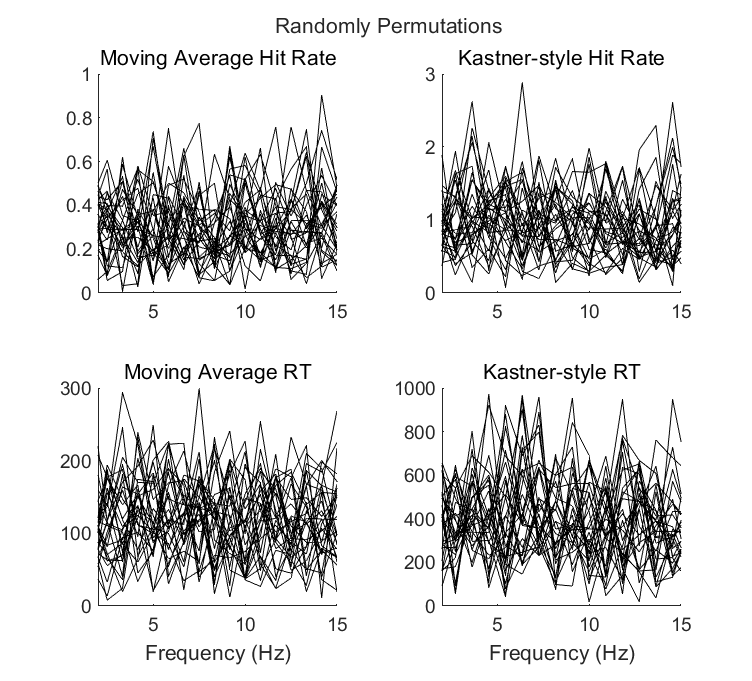

randomLines = 30;
hitRateMoveMean83R  = nan(length(hitRateMoveMean83), randomLines);
hitRateKastner100R  = nan(length(hitRateKastner100), randomLines);
RTMoveMean83R       = nan(length(RTMoveMean83), randomLines);
RTKastner100R       = nan(length(RTKastner100), randomLines);

for n = 1:randomLines
    hitRateMoveMean83R(:,n) = hitRateMoveMean83(randperm(length(hitRateMoveMean83)));
    hitRateKastner100R(:,n) = hitRateKastner100(randperm(length(hitRateKastner100)));
    RTMoveMean83R(:,n)      = RTMoveMean83(randperm(length(RTMoveMean83)));
    RTKastner100R(:,n)      = RTKastner100(randperm(length(RTKastner100)));
end
   
FFT_HitRateMoveMean83R  = fft(hitRateMoveMean83R, 72, 1);
FFT_HitRateKastner100R  = fft(hitRateKastner100R, 1100, 1);
FFT_RTMoveMean83R       = fft(RTMoveMean83R, 72, 1);
FFT_RTKastner100R       = fft(RTKastner100R, 1100, 1);

figure('Units', 'inches', 'OuterPosition', [0.5, 0.5, 8, 7.5])
t = tiledlayout(2, 2);
title(t, "Randomly Permutations", "FontSize", 16)
nexttile
    plot(xValsMoveMeanFourier(2:end), abs(FFT_HitRateMoveMean83R(2:end, :)), "k")
    box off
    xlim([2 15])
    ax = gca;
    ax.FontSize = 14;
    title("Moving Average Hit Rate", "FontSize", 16, "FontWeight", "normal")
nexttile
    plot(xValsKastner100Fourier(2:end), abs(FFT_HitRateKastner100R(2:end, :)), "k")
    box off
    xlim([2 15])
    ax = gca;
    ax.FontSize = 14;
    title("Kastner-style Hit Rate", "FontSize", 16, "FontWeight", "normal")
nexttile
    plot(xValsMoveMeanFourier(2:end), abs(FFT_RTMoveMean83R(2:end, :)), "k")
    box off
    xlim([2 15])
    ax = gca;
    ax.FontSize = 14;
    title("Moving Average RT", "FontSize", 16, "FontWeight", "normal")
    xlabel("Frequency (Hz)", "FontSize", 16)
nexttile
    plot(xValsKastner100Fourier(2:end), abs(FFT_RTKastner100R(2:end, :)), "k")
    box off
    xlim([2 15])
    ax = gca;
    ax.FontSize = 14;
    title("Kastner-style RT", "FontSize", 16, "FontWeight", "normal")
    xlabel("Frequency (Hz)", "FontSize", 16)
exportgraphics(gcf, "Random Perumtation Fourier Lines.png", 'Resolution', 300)

### Random order analysis with mean and standard deviation

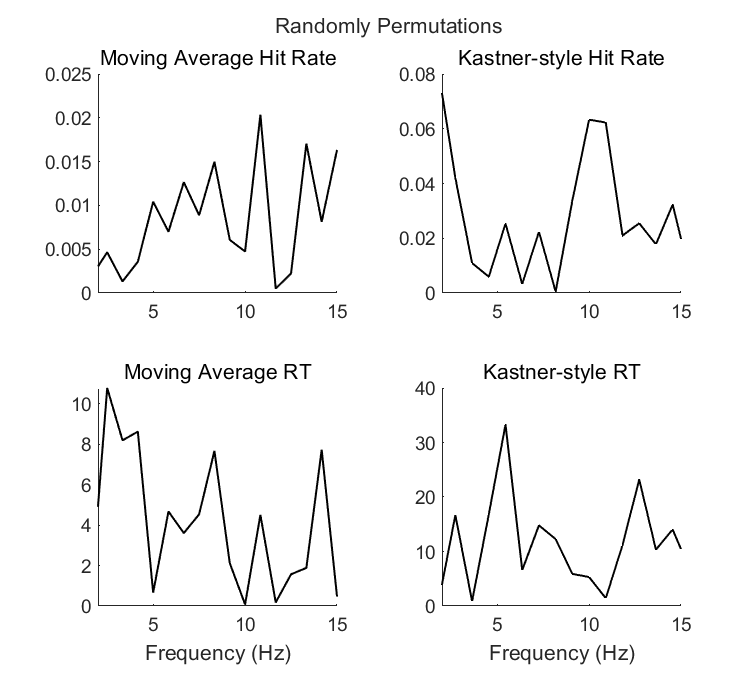

randomLines = 1000;
hitRateMoveMean83R = nan(length(hitRateMoveMean83), randomLines);
hitRateKastner100R  = nan(length(hitRateKastner100), randomLines);
RTMoveMean83R      = nan(length(RTMoveMean83), randomLines);
RTKastner100R       = nan(length(RTKastner100), randomLines);

for n = 1:randomLines
    hitRateMoveMean83R(:,n) = hitRateMoveMean83(randperm(length(hitRateMoveMean83)));
    hitRateKastner100R(:,n)  = hitRateKastner100(randperm(length(hitRateKastner100)));
    RTMoveMean83R(:,n)      = RTMoveMean83(randperm(length(RTMoveMean83)));
    RTKastner100R(:,n)       = RTKastner100(randperm(length(RTKastner100)));
end
   
FFT_HitRateMoveMean83R = fft(hitRateMoveMean83R, 72, 1);
FFT_HitRateKastner100R  = fft(hitRateKastner100R, 1100, 1);
FFT_RTMoveMean83R       = fft(RTMoveMean83R, 72, 1);
FFT_RTKastner100R       = fft(RTKastner100R, 1100, 1);

Real_HitRateMoveMean83R_Mn  = mean(real(FFT_HitRateMoveMean83R), 2);
Real_HitRateKastner100R_Mn  = mean(real(FFT_HitRateKastner100R), 2);
Real_RTMoveMean83R_Mn       = mean(real(FFT_RTMoveMean83R), 2);
Real_RTKastner100R_Mn       = mean(real(FFT_RTKastner100R), 2);

Imag_HitRateMoveMean83R_Mn  = mean(imag(FFT_HitRateMoveMean83R), 2);
Imag_HitRateKastner100R_Mn  = mean(imag(FFT_HitRateKastner100R), 2);
Imag_RTMoveMean83R_Mn       = mean(imag(FFT_RTMoveMean83R), 2);
Imag_RTKastner100R_Mn       = mean(imag(FFT_RTKastner100R), 2);

FFT_HitRateMoveMean83R_Mn   = Real_HitRateMoveMean83R_Mn + Imag_HitRateMoveMean83R_Mn;
FFT_HitRateKastner100R_Mn   = Real_HitRateKastner100R_Mn + Imag_HitRateKastner100R_Mn;
FFT_RTMoveMean83R_Mn        = Real_RTMoveMean83R_Mn + Imag_RTMoveMean83R_Mn;
FFT_RTKastner100R_Mn        = Real_RTKastner100R_Mn + Imag_RTKastner100R_Mn;

figure('Units', 'inches', 'OuterPosition', [0.5, 0.5, 8, 7.5])
t = tiledlayout(2, 2);
title(t, "Randomly Permutations", "FontSize", 16)
nexttile
    plot(xValsMoveMeanFourier(2:end), abs(FFT_HitRateMoveMean83R_Mn(2:end)), "k", "LineWidth", 1.5)
    box off
    xlim([2 15])
    ax = gca;
    ax.FontSize = 14;
    title("Moving Average Hit Rate", "FontSize", 16, "FontWeight", "normal")
nexttile
    plot(xValsKastner100Fourier(2:end), abs(FFT_HitRateKastner100R_Mn(2:end)), "k", "LineWidth", 1.5)
    box off
    xlim([2 15])
    ax = gca;
    ax.FontSize = 14;
    title("Kastner-style Hit Rate", "FontSize", 16, "FontWeight", "normal")
nexttile
    plot(xValsMoveMeanFourier(2:end), abs(FFT_RTMoveMean83R_Mn(2:end)), "k", "LineWidth", 1.5)
    box off
    xlim([2 15])
    ax = gca;
    ax.FontSize = 14;
    title("Moving Average RT", "FontSize", 16, "FontWeight", "normal")
    xlabel("Frequency (Hz)", "FontSize", 16)
nexttile
    plot(xValsKastner100Fourier(2:end), abs(FFT_RTKastner100R_Mn(2:end)), "k", "LineWidth", 1.5)
    box off
    xlim([2 15])
    ax = gca;
    ax.FontSize = 14;
    title("Kastner-style RT", "FontSize", 16, "FontWeight", "normal")
    xlabel("Frequency (Hz)", "FontSize", 16)
exportgraphics(gcf, "Random Permutation Fouriers Averaged.png", 'Resolution', 300)